clear
clc

# VTail Calculator V1

#### By James Orendi

## VTail Sizing & Design

wing_area = 0.5 ; % m^2, Predicted Wing Area of Aircraft, for use in Tail Volume Analysis
wing_span = 0.2 ; % m, Predicted Wingspan of Aircraft, for use in Tail Volume Analysis

C_V = 0.1275 ; % N/A, Tail Volume Coefficient
S_V_S = 0.375 ; % N/A, Tail to Wing Area Ratio

AR_V = 2 ; % N/A, Aspect Ratio of Tail
Vtail_TR =0.7 ; % Horizontal tail taper ratio

sweep_type = 4 ;
Vtail_sweep = 0 ; % Horizontal Tail Sweepback, deg

Vtail_no = 1 ; % N/A, Number of Vtails (Assumed Identical)


Vtail_dihedral =  0 ; % degrees

#### Function Call

addpath([cd,'/Functions'])
[Vtail_area,~] = Tail_Volume_Analysis(wing_area,C_V,S_V_S,wing_span) ;
[x_Vtail_data,y_Vtail_data,V_span,V_c_r,V_c_t,Vtail_opp,Vtail_sweep,~,Vtail_opp_2,Vtail_adj_2,Vtail_xlim,Vtail_ylim] = Planform_Calc_1taper(2*Vtail_area,AR_V,Vtail_TR,Vtail_dihedral,Vtail_sweep,sweep_type) ;

#### MAC Graphical Calculation Function Call

[y_mac_Vtail_data_1,y_mac_Vtail_data_2,y_mac_Vtail_data_3,y_mac_Vtail_data_4,x_mac_Vtail_data_1,x_mac_Vtail_data_2,Vtail_mac_graph_line_x_points,Vtail_mac_graph_line_1_data,Vtail_mac_graph_line_2_data,Vtail_mac_graph_data_y,Vtail_mac_graph_data_x,Vtail_graph_AC,Vtail_quarter_chord_x,Vtail_quarter_chord_y] = Planform_MAC_1taper(V_span,V_c_t,V_c_r,Vtail_opp);

### Vtail MAC Graphical Plot

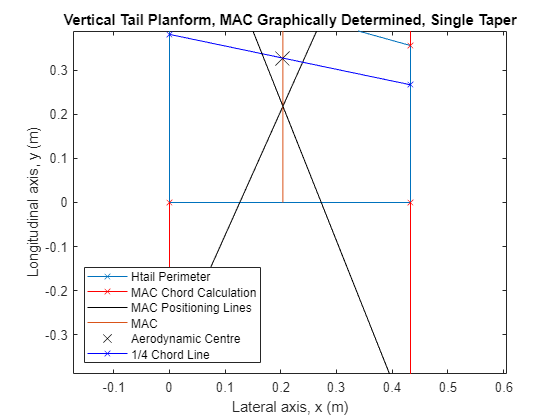

figure
plot(x_Vtail_data,y_Vtail_data,'x-')
hold on
plot(x_mac_Vtail_data_1,y_mac_Vtail_data_1,'x-','Color','r')
plot(Vtail_mac_graph_line_x_points,Vtail_mac_graph_line_1_data,'-','Color','k')
plot(Vtail_mac_graph_data_x,Vtail_mac_graph_data_y,'-','Color',[0.8500 0.3250 0.0980])
plot(Vtail_graph_AC(1),Vtail_graph_AC(2),'x', 'Color','k','MarkerSize',15)
plot(Vtail_quarter_chord_x,Vtail_quarter_chord_y,'x-', 'Color','b')
plot(Vtail_mac_graph_line_x_points,Vtail_mac_graph_line_2_data,'-','Color','k')
plot(x_mac_Vtail_data_1,y_mac_Vtail_data_2,'x-','Color','r')
plot(x_mac_Vtail_data_2,y_mac_Vtail_data_3,'x-','Color','r')
plot(x_mac_Vtail_data_2,y_mac_Vtail_data_4,'x-','Color','r')
xlim([Vtail_xlim(1),Vtail_xlim(2)]) % Graphical Display View limits, x axis
ylim([-Vtail_ylim,Vtail_ylim]) % Graphical Display View limits, y axis
legend("Htail Perimeter","MAC Chord Calculation","MAC Positioning Lines","MAC","Aerodynamic Centre","1/4 Chord Line","Location","Southwest")
title("Vertical Tail Planform, MAC Graphically Determined, Single Taper")
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")
hold off

## Vtail Control Surface Sizing

### Input Data

rudder_area_ratio_desired = 30/100 ; % N/A, Ratio of Control Surface Area to Vertical Tail Area

CS_type = 1 ;

% SPANWISE PIVOT
Vtail_span_ratio = 0.8 ; % N/A, Ratio of Control Surface Span to Vertical Tail Span, for Spanwise Pivot ONLY

% CONSTANT CHORD
rudder_chord_ratio = 0.5 ; % N/A, Ratio of Control Surface Chord to Vertical Tail Chord, for Constant Chord ONLY

#### Function Call

if CS_type == 1
    [Vtail_x_control_surface_data,Vtail_y_control_surface_data] = CS_Spanwise_Pivot(rudder_area_ratio_desired,Vtail_span_ratio,Vtail_opp_2,Vtail_adj_2,V_span,V_c_r,V_c_t,Vtail_opp,Vtail_sweep) ;
elseif CS_type == 2
    [Vtail_x_control_surface_data,Vtail_y_control_surface_data,Htail_S_control_ratio] = CS_Constant_Chord(rudder_area_ratio_desired,Vtail_opp_2,Vtail_adj_2,V_span,Vtail_sweep,rudder_chord_ratio,V_c_r,V_c_t,Vtail_opp) ;
end

### Full Horizontal Tail Control Surface Planform Plot

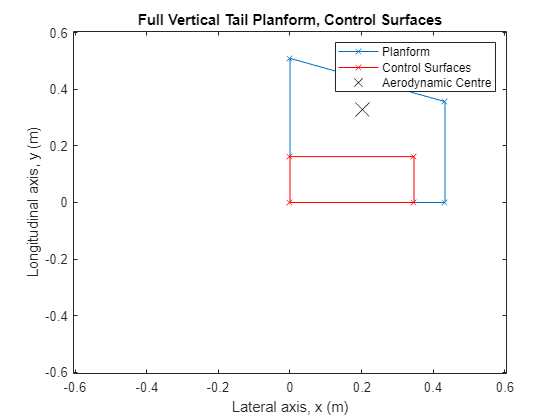

figure
plot(x_Vtail_data,y_Vtail_data,'x-',"Color",[0 0.4470 0.7410])
hold on
plot(Vtail_x_control_surface_data,Vtail_y_control_surface_data,'x-',"Color",'r')
plot(Vtail_graph_AC(1),Vtail_graph_AC(2),'x', 'color','k','MarkerSize',15)

title("Full Vertical Tail Planform, Control Surfaces")
legend("Planform","Control Surfaces","Aerodynamic Centre")
xlim([-Vtail_xlim(2),Vtail_xlim(2)]) % Graphical Display View limits, x axis
ylim([-Vtail_xlim(2),Vtail_xlim(2)]) % Graphical Display View limits, y axis
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")
hold off